%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 验证两种噪声添加方式的差异
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc;clear;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 数据准备
%------------------------------
% 旋转矩阵
R_true=[0.689673028293550	0.423447870703166	0.587403621746887
        0.176155229057263	0.688715772969376	-0.703306419236294
        -0.702367745073895	0.588525687510876	0.400396136119796];
% 平移矢量
t_true = [2;3;4];

% 数据大小
num = 100;

%
stdVar_noise = [0.00001,0.00001,0.0001,0.001,0.01,0.1];
% stdVar_noise = [0.000001];

% 生成俯仰角 [-6°, 6°] 转换为弧度
elevation_angles = deg2rad(-10 + 20*rand(1, num));
% 生成方位角 [-π/4, π/4]
azimuth_angles = (-pi/6) + (pi/3) * rand(1, num);
% 生成距离 [0, 5] 米
d_true = 6 * rand(1, num);

% 生成 p_s
p_s(1,:)= (d_true .* cos(elevation_angles) .* cos(azimuth_angles));
p_s(2,:)= (d_true .* cos(elevation_angles) .* sin(azimuth_angles));
p_s(3,:)= (d_true .* sin(elevation_angles))';

% 生成 p_si
p_si(1,:)= d_true .* cos(azimuth_angles);
p_si(2,:)= d_true .* sin(azimuth_angles);


% 生成 p_w
p_w = R_true*p_s+t_true;



for n =1:length(stdVar_noise)
    n
%     M = 1;
    M = 1000;
    
    error_t = 0;
    error_R = 0;

    error_t_tan = 0;
    error_R_tan = 0;

    for j = 1:M
        %----------------------------------
        % 生成噪声数据 加在theta上
        % 噪声的标准差
        stdVar_noise_d = stdVar_noise(1,n);
        stdVar_noise_theta = stdVar_noise(1,n);
        
        d_noise = d_true + stdVar_noise_d*randn(1, num);
        
        noise_on_theta = stdVar_noise_theta*randn(1, num);
        theta_noise =  azimuth_angles + noise_on_theta;
        
        p_si_noise(1,:)= d_noise .* cos(theta_noise);
        p_si_noise(2,:)= d_noise .* sin(theta_noise);
        
        %----------------------------------
        % 生成噪声数据 加在tan上、
        tan_theta = tan(azimuth_angles);
        tan_theta_noise = tan_theta + noise_on_theta;
        
        theta_noise_tan= atan(tan_theta_noise);

        
        cos_theta_noise_tan = cos(theta_noise_tan);
        sin_theta_noise_tan = sin(theta_noise_tan);
        p_si_noise_tan = [d_noise.*cos_theta_noise_tan;d_noise.*sin_theta_noise_tan];

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % 估计 R 和 t
        [R,t] = BESTAnP(p_w,p_si_noise);;

        [R_tan,t_tan] = BESTAnP(p_w,p_si_noise_tan);


      
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %计算估计偏差

        s = rotm2eul(R*R_true','XYZ');
        error_R = error_R+ norm(s)^2;

        error_t = error_t+ norm(t-t_true)^2;

        s_tan = rotm2eul(R_tan*R_true','XYZ');
        error_R_tan = error_R_tan+ norm(s_tan)^2;

        error_t_tan = error_t_tan+ norm(t_tan-t_true)^2;


    end

    [crlb_R,crlb_t] = Calculate_CRLB(p_w,R_true,t_true,stdVar_noise_d,stdVar_noise_theta);

    CRLB_t_x(n,:) = sqrt(crlb_t);
    CRLB_R_x(n,:) = sqrt(crlb_R);

    



    Error_t(n,:) = sqrt(error_t/M);
    Error_R(n,:) = sqrt(error_R/M);


    Error_t_tan(n,:) = sqrt(error_t/M);
    Error_R_tan(n,:) = sqrt(error_R_tan/M);
end




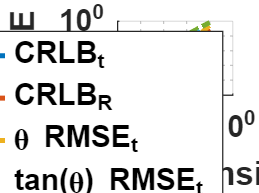

% Var_noise_base_x = stdVar_noise;
figure
grid on 
hold on;


loglog(stdVar_noise,CRLB_t_x,'LineWidth', 2,  'MarkerSize', 5);
loglog(stdVar_noise,CRLB_R_x,'LineWidth', 2,  'MarkerSize', 5);


loglog(stdVar_noise,Error_t,'-.','LineWidth', 2, 'MarkerSize', 5);
loglog(stdVar_noise,Error_t_tan,'--','LineWidth', 2, 'MarkerSize', 5);

loglog(stdVar_noise,Error_R,'-.','LineWidth', 2, 'MarkerSize', 5);
loglog(stdVar_noise,Error_R_tan,'--','LineWidth', 2, 'MarkerSize', 5);

legend('CRLB_t','CRLB_R','\theta RMSE_t','tan(\theta) RMSE_t','\theta RMSE_R','tan(\theta) RMSE_R','FontSize', 12, 'FontWeight', 'bold');

xlabel('Noise Intensity','FontSize', 12, 'FontWeight', 'bold');
ylabel('RMSE','FontSize', 12, 'FontWeight', 'bold');
set(gca, 'XScale', 'log', 'YScale', 'log','FontSize', 12, 'FontWeight', 'bold');